# Skull Pose stimation

Think about going from Robot Frame to three point that can be measured.

close all 
clear

## Simulated enviroment 

Generating three point in space P_B

P_A=[0 1 0 1;0 0 0 1; 1 0 0 1]'

P_A =      0     0     1
     1     0     0
     0     0     0
     1     1     1


Use a known R_A_B

R_A_B=eul2tr(0.1,0.2,0.3)

R_A_B =     0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


P_B=R_A_B*P_A

P_B =    -0.3836         0    0.9021
    0.9216         0    0.3875
    0.0587         0   -0.1898
    1.0000    1.0000    1.0000


## Using Puma to measure 

We measure P_B using the Puma Robot. One of them (second one) will be use to stablish P_BORG.

Based on the other two we have to recover the R_B_A.

From know on points P_B are measured in Robot Reference Frame {RF}

## Displaying the concepts

figure
axis ([-0.5 1.5 -0.5 1.5 -0.5 1.5])
hold on
% labelling
zlabel('z');ylabel('y');xlabel('x');
grid on

Triangles

fill3(P_A(1,:),P_A(2,:),P_A(3,:),'g') % it is coincident with Robot Frame
fill3(P_B(1,:),P_B(2,:),P_B(3,:),'b') 
alpha 0.2

Enhanced Points P_B }

[x,y,z] = sphere;
surf(0.015*x+P_B(1,1),0.015*y+P_B(2,1),0.015*z+P_B(3,1))  
surf(0.015*x+P_B(1,2),0.015*y+P_B(2,2),0.015*z+P_B(3,2))  
surf(0.015*x+P_B(1,3),0.015*y+P_B(2,3),0.015*z+P_B(3,3))
text(P_B(1,1)+0.05,P_B(2,1),P_B(3,1) ,{'A'},'FontSize',14)
text(P_B(1,2)+0.05,P_B(2,2),P_B(3,2) ,{'B'},'FontSize',14)
text(P_B(1,3)+0.05,P_B(2,3),P_B(3,3) ,{'C'},'FontSize',14)

Reference Frames

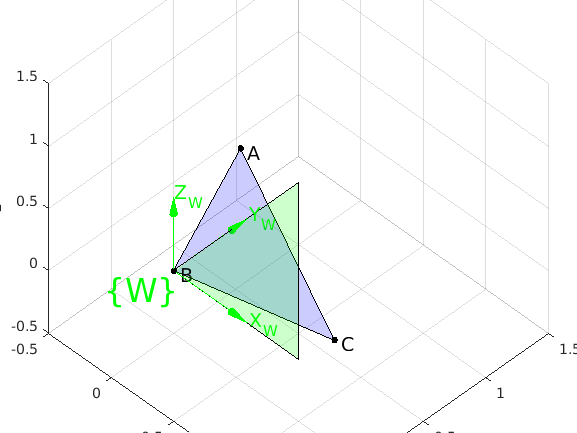

trplot(eye(4), 'frame','W','length',0.6,'text_opts', {'FontSize', 14},'arrow','color', 'g','thick',1)
view(45,45)

## Unitary vectors of P_B

 AB=(P_B(1:3,1)-P_B(1:3,2))/norm(P_B(1:3,1)-P_B(1:3,2)); % Vector pointing A 
 norm(AB)

ans = 1

 CB=(P_B(1:3,3)-P_B(1:3,2))/norm(P_B(1:3,2)-P_B(1:3,3)); % Vector pointing C
 norm(CB)

ans = 1

## Frame description extracted from the triangle A - B - C

Orientation vector: Approach: â --> Z; See page 40 of Peter Corke book: Robotics, Vision and Control 

 Z_B=cross(CB, AB)/norm(cross(CB, AB))% Perpendicular to BA & CB equivalent to â; Z point up

Z_B =     0.1977
    0.0198
    0.9801


 O_B_A =oa2r(AB, Z_B) % AB is the orientation vector (y axis ô) and Z_B is tha aproach axis (z axis â). The result ^n is in x axis

O_B_A =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


Displaying the {nB} coincident with {B}

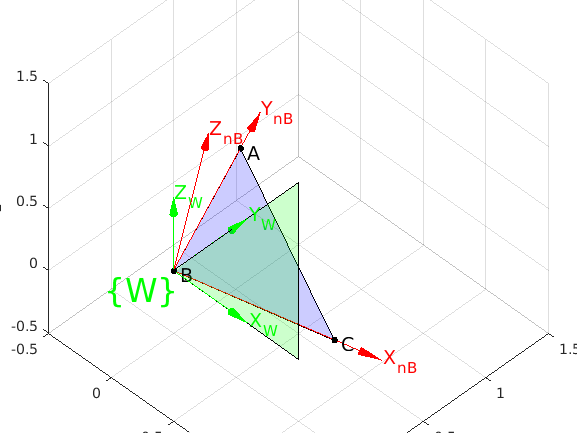

 trplot(eye(4), 'frame','W','length',0.6,'text_opts', {'FontSize', 14},'arrow','color', 'g','thick',1)
 trplot(O_B_A, 'frame','nB','length',1.3,'text_opts', {'FontSize', 14},'arrow','color', 'r','thick',1)
 view(45,45)

## Frame description skull with respect to Robot Frame

P_Borg=[1 2 3]' % Extracted from Puma measurement.

P_Borg =      1
     2
     3


T_Skull_RF=[O_B_A P_Borg; 0 0 0 1]

T_Skull_RF =     0.9021   -0.3836    0.1977    1.0000
    0.3875    0.9216    0.0198    2.0000
   -0.1898    0.0587    0.9801    3.0000
         0         0         0    1.0000
